## 时间序列分析

- 时间序列是按时间顺序、通常以规则间隔采样的数据向量。

- 时间序列表示动态总体或过程的时间演化。

- 时间序列分析涉及：

- 识别模式

- 建模模式

- 预测值

### 时间序列类型及其用途

MATLAB 时间序列对象有两种类型：

- `timeseries`— 存储数据和时间值，以及包括单位、事件、数据质量和插值方法的元数据信息

- `tscollection`— 存储共享一个公共时间向量的 `timeseries`对象集合，便于对具有不同单位的同步时间序列执行操作

### 时间序列数据样本

- 数据值与数据样本之间的区别

- 数据值是在特定时间记录的单个标量值。

- 数据样本由与 `timeseries`对象中特定时间关联的一个或多个值组成。

- 时间序列中的数据样本数量与时间向量的长度相同。

- 例如，考虑由三个传感器信号组成的数据：两个信号表示物体以米为单位的位置，第三个表示其以米/秒为单位的速度。

- 考虑以下数据矩阵，其中 NaN 值表示缺失数据值。

- x 的前两列包含具有相同单位的量，您可以创建一个多变量 `timeseries`对象来存储这两个时间序列。

- 时间向量的长度（在此示例中为 5）等于 `timeseries`对象中的数据样本数。

x = [-0.2 -0.3 13;
-0.1 -0.4 15;
NaN 2.8 17;
0.5 0.3 NaN;
-0.3 -0.1 15]

x =    -0.2000   -0.3000   13.0000
   -0.1000   -0.4000   15.0000
       NaN    2.8000   17.0000
    0.5000    0.3000       NaN
   -0.3000   -0.1000   15.0000


ts_pos = timeseries(x(:,1:2), 1:5, 'name', 'Position')

  timeseries

  Common Properties:
            Name: 'Position'
            Time: [5x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [5x2 double]
        DataInfo: 

ts_vel = timeseries(x(:,3), 1:5, 'name', 'Velocity');

### 创建时间序列对象

对于来自 `count.dat`的样本数据，创建三个 `timeseries`对象来存储在每个交叉路口收集的数据。

load count.dat
count1 = timeseries(count(:,1), 1:24,'name', 'intersection1');
count2 = timeseries(count(:,2), 1:24,'name', 'intersection2');
count3 = timeseries(count(:,3), 1:24,'name', 'intersection3');

### 修改时间序列单位

- 将 `count1`的数据单位更改为 'cars'。

- 通过将 `count1`的插值方法设置为零阶保持，将离散时间值转换为连续时间。这会将每个样本值保持一个采样间隔。

- 将三个时间序列的时间单位修改为 'hours'。

load count.dat
count1 = timeseries(count(:,1), 1:24,'name', 'intersection1');
count2 = timeseries(count(:,2), 1:24,'name', 'intersection2');
count3 = timeseries(count(:,3), 1:24,'name', 'intersection3');
count1.DataInfo.Units = 'cars';
count1.DataInfo.Interpolation = tsdata.interpolation('zoh');
count1.TimeInfo.Units = 'hours';
count2.TimeInfo.Units = 'hours';
count3.TimeInfo.Units = 'hours';

### 定义事件

- 事件在特定时间标记数据。

- 向数据添加两个事件，标记上午 8 点通勤和下午 6 点通勤的时间。

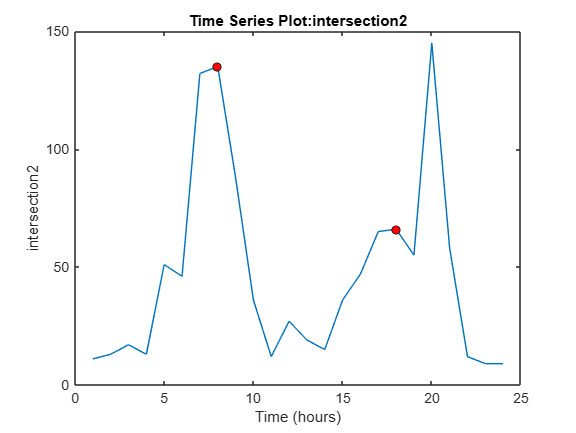

load count.dat
count1 = timeseries(count(:,1), 1:24,'name', 'intersection1');
count2 = timeseries(count(:,2), 1:24,'name', 'intersection2');
count3 = timeseries(count(:,3), 1:24,'name', 'intersection3');
count1.DataInfo.Units = 'cars';
count1.DataInfo.Interpolation = tsdata.interpolation('zoh');
count1.TimeInfo.Units = 'hours';
count2.TimeInfo.Units = 'hours';
count3.TimeInfo.Units = 'hours';
e1 = tsdata.event('AMCommute',8);
e1.Units = 'hours'; % 指定时间的单位
count1 = addevent(count1,e1); % 将事件添加到 count1
count2 = addevent(count2,e1); % 将事件添加到 count2
count3 = addevent(count3,e1); % 将事件添加到 count3
e2 = tsdata.event('PMCommute',18);
e2.Units = 'hours'; % 指定时间的单位
count1 = addevent(count1,e2); % 将事件添加到 count1
count2 = addevent(count2,e2); % 将事件添加到 count2
count3 = addevent(count3,e2); % 将事件添加到 count3
figure
plot(count2)

### 创建时间序列集合对象

集合中的每个单独时间序列称为一个成员。

tsc = tscollection({count1 count2},'name', 'count_coll')


Time Series Collection Object: count_coll

Time vector characteristics

      Start time            1 hours
      End time              24 hours

Member Time Series Objects:

      intersection1
      intersection2




tsc = addts(tsc, count3)


Time Series Collection Object: count_coll

Time vector characteristics

      Start time            1 hours
      End time              24 hours

Member Time Series Objects:

      intersection1
      intersection2
      intersection3




### 重采样时间序列集合对象

- 在每个半小时标记处插值。

- 使用时间序列的默认插值方法。

tsc1 = resample(tsc,1:0.5:24)


Time Series Collection Object: count_coll

Time vector characteristics

      Start time            1 hours
      End time              24 hours

Member Time Series Objects:

      intersection1
      intersection2
      intersection3




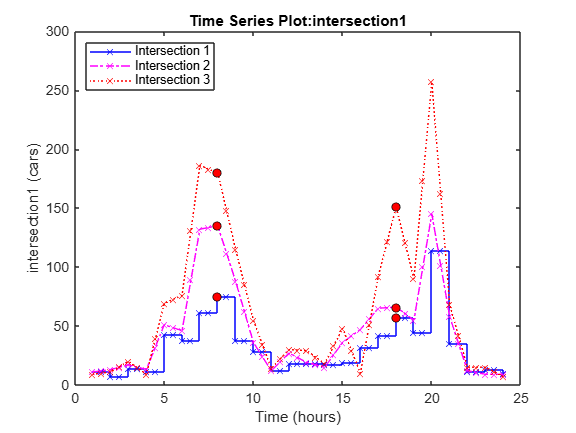

hold off

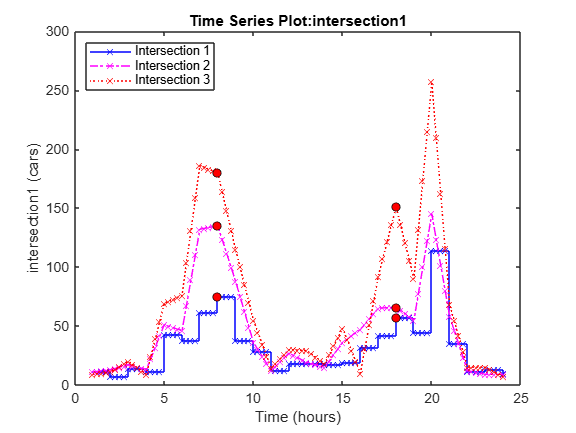

plot(tsc1.intersection1,'-xb','Displayname','Intersection 1')
hold on
plot(tsc1.intersection2,'-.xm','Displayname','Intersection 2')
plot(tsc1.intersection3,':xr','Displayname','Intersection 3')
legend('show','Location','NorthWest')

### 添加/移除数据样本

**向 'intersection1' 添加一个数据样本**

- 问：'intersection2' 和 'intersection3' 在 3.25 小时的值是多少？

tsc1 = addsampletocollection(tsc1,'time',3.25,'intersection1',5);

**移除缺失数据**

- 问：'intersection1' 中的数据是否保留？

tsc1 = delsamplefromcollection(tsc1,'index',find(isnan(tsc1.intersection2.Data)));

**插值缺失数据**

tsc1 = addsampletocollection(tsc1,'time',3.25,'intersection1',5);
tsc1 = resample(tsc1,tsc1.Time);